# The AstroUtil package

# in the astronomy & astrophysics toolbox for MATLAB

## Description:

The AstroUtil package contains several sub packages that deals with astrophysical phenomena (e.g., cosmological distances, binary stars).

To view all the functions type: "`AstroUtil.`" followed by <tab>.

To avoid using the "`AstroUtil.cosmo.ad_dist`" syntax, you can use:

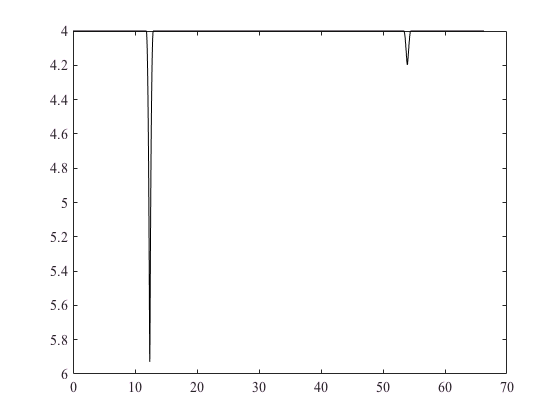

import AstroUtil.*
help cosmo.ad_dist

This file is accessible through "`AstroUtil.manual`".

## Credit

If you are using this code or products in your scientific publication please give a reference to [Ofek (2014; ascl.soft 07005)](http://adsabs.harvard.edu/abs/2014ascl.soft07005O).

## License

Unless specified otherwise this code and products are released under the GNU general public license version 3.

## Installation

See[ http://weizmann.ac.il/home/eofek/matlab/doc/install.html ](http://webhome.weizmann.ac.il/home/eofek/matlab/doc/install.html)for installation instruction and additional documentation.

# List of sub packages

## The binary star package

Contains some functions related to binary stars, including generation of eclipsing binary light curves, radial velocity, and astrometric binaries.

**Eclipsing binaries:**

The function `AstroUtil.binary.eb_demo` will open a GUI interface to generate eclipsing binary light curves.

The following example will generate a light curve of eclipsing binary:

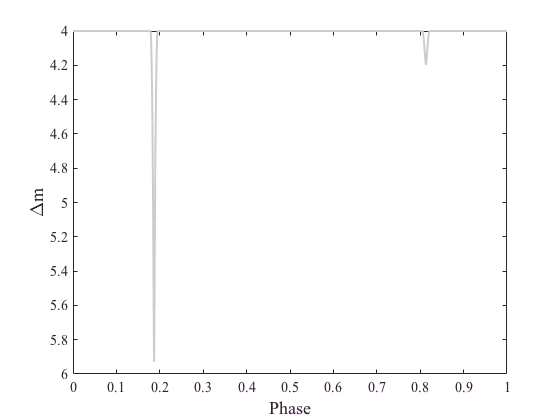

[LC,Period]=AstroUtil.binary.eb_light_curve([100 20],[1 0.6],[0.01 0.01],[0 0.3 0.2 0 0 pi./2],'AstroUtil.binary.limb_darkening');

plot(LC(:,1),LC(:,2),'k-'); invy


while the following example will plot the phase folded light curve:

AstroUtil.binary.plot_eb_lc_ph([100 20],[1 0.6],[0.01 0.01],[0 0.3 0.2 0 0 pi./2],'AstroUtil.binary.limb_darkening');

**Additional functions relevant for eclipsing binaries are:**

`AstroUtil.binary.binary_reflection_effect` - Calculate reflection effects.

`AstroUtil.binary.limb_darkening` - Calculate limb darkening.

`AstroUtil.binary..obstruction` - Calculate the obstruction for eclipsing binary

`AstroUtil.binary.plot_eb_lc` - Plot the light curve of eclipsing binary

`AstroUtil.binary.total_light` - Calculate the total light given the limb darkening

**Spectroscopic binaries**

Use AstroUtil.binary.binary_rv to calculate the radial velocity of a binary.

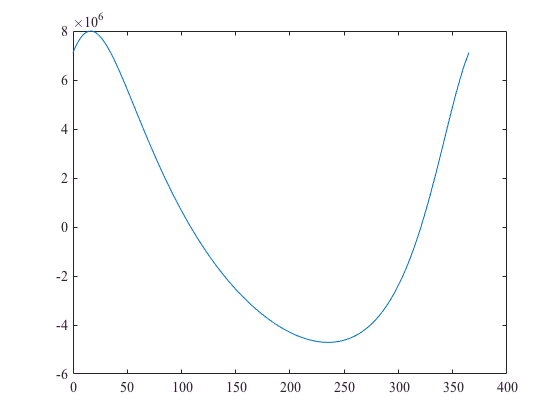

t=[0:1:365].';
e=0.3;
a=1;
RAD = 180./pi;
RV=AstroUtil.binary.binary_rv(t,365,0,a./(1-e),e,85./RAD,100);

plot(t,RV)

**Fitting spectroscopic binaries**

The function `AstroUtil.binary.fit_rv_ellipse `can be used to fit radial velocity measurments, and specifically to calculate the periodogram for RV.

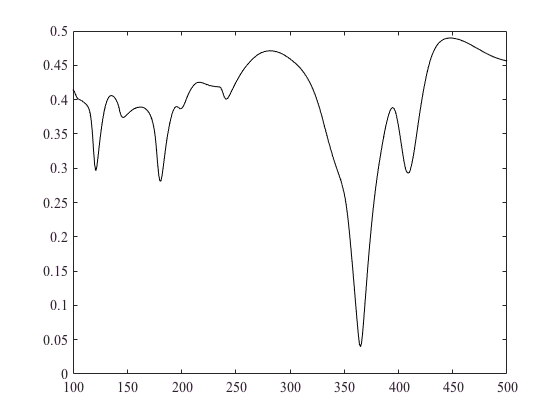

Time = (1:1:700)';
% define the orbital elements
P    = 365;
T    = 0;
q    = 1;
e    = 0.6;
i    = 1;
omega = 3.9;
Nt = numel(Time);
% generate RV curve
[RV,K2] = AstroUtil.binary.binary_rv(Time,P,T,q,e,i,omega);
RV = RV./1e5;
RV = RV + randn(Nt,1);
% calculate the periogogram
VecP = (100:1:500)';
[Res,FreqVec]=AstroUtil.binary.fit_rv_ellipse(Time,RV,VecP);
% plot the rms vs. the period
plot(VecP,[Res.RMS]','k-');

This function uses additional useful functions like: `AstroUtil.binary.rv2ellipse `and` fit_ellipse`.

**Equipotentials**

The following example plot the equipotential surface for a binary system:

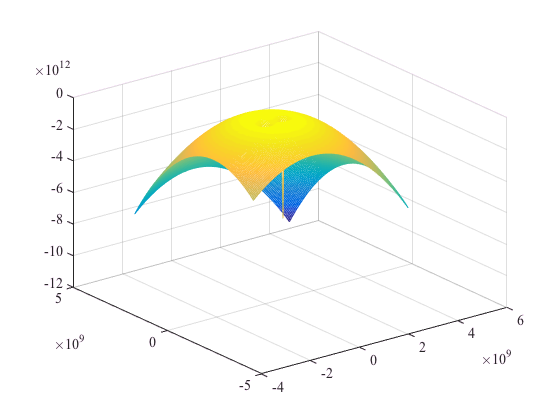

[x,y,q]=AstroUtil.binary.equipot(1,0.7,0.7.*1e9,3,50);
mesh(x,y,q);

## The cosmology package

The `cosmo` package contains function for evaluating cosmological distances and related properties.

Examples related to cosmological distance calculators:

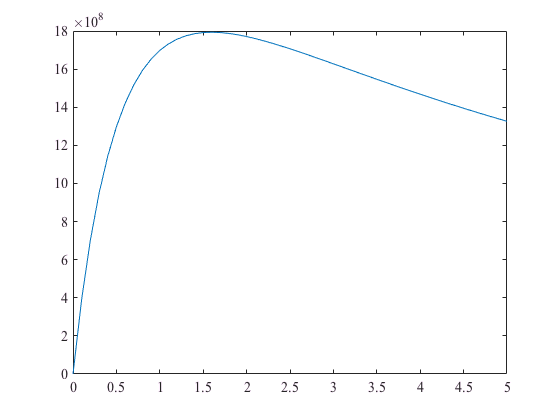

import AstroUtil.cosmo.*
z=(0:0.1:5)';
% calculate angular diameter distance
D=ad_dist(z);
plot(z,D)

% calculate lookback time
T = lookback_time(z);

ans =    6.3872e+08


ans =    7.2687e+07


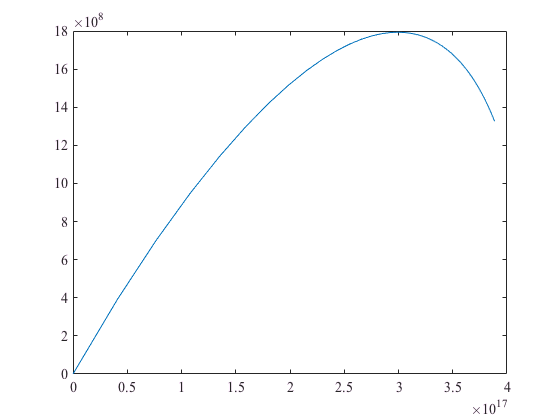

% plot angular diameter distance as a function of lookback time [s]
plot(T,D)

Functions like `ad_dist` and `lookback_time` support calculations of distances/times between two redshifts:

% calculate angular diameter distance [pc] between z1 and z2
z1=1;

Par =            H0: 67.74
       OmegaM: 0.3089
     OmegaRad: 0
       OmegaL: 0.6911
    OmegaB_h2: 0.0223
       sigma8: 0.8159
         z_re: 8.8
          Age: 13.799


ErrPar =            H0: [0.46 0.46]
       OmegaM: [0.0062 0.0062]
       OmegaL: [0.0062 0.0062]
    OmegaB_h2: [0.00014 0.00014]
       sigma8: [0.0086 0.0086]
         z_re: [1.1 1.2]
          Age: [0.021 0.021]


z2=2;
ad_dist([z1 z2])

D =             0
   3.8444e+08
   6.8841e+08
    9.301e+08
   1.1228e+09
   1.2766e+09
   1.3992e+09
   1.4965e+09
   1.5734e+09
   1.6335e+09
     1.68e+09


% note this is not the same as:
ad_dist(z2)-ad_dist(z1) 
% The last calculation is incorrect and should not be used!


Most functions allow to control the cosmological parameters used in the calculations. The function `AstroUtil.cosmo.cosmo_pars` store various cosmological parameters:

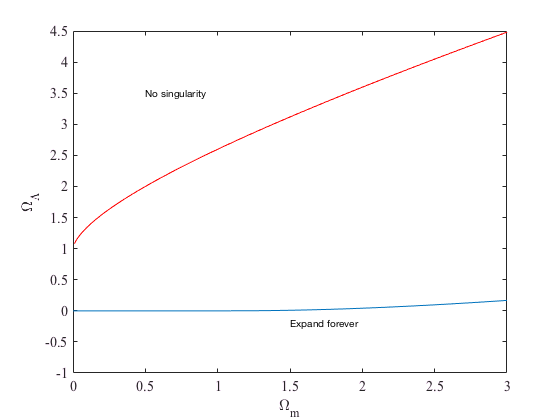


[Par,ErrPar]=AstroUtil.cosmo.cosmo_pars('planck')
z=(0:0.1:1)';
D=AstroUtil.cosmo.ad_dist(z,'wmap9');
% or you can provide the parameters directly:
H0=100;
OmegaM = 0.3;

OmegaL = 0.7;
D=AstroUtil.cosmo.ad_dist(z,[H0,OmegaM,OmegaL]);


Additional related functions:

- `AstroUtil.cosmo.lum_dist `- Calculate the luminosity distance

- `AstroUtil.cosmo.inv_lum_dist `- Convert luminosity distance to redshift

- `AstroUtil.cosmo.dist_mod2dist `- Convert distance modulus to luminosity distance

- `AstroUtil.cosmo.comoving_dist` - Calculate the comoving distance

- `AstroUtil.cosmo.hubble_z` - Calculate H0 as a function of redshift

- `AstroUtil.cosmo.comoving_volume` - Calculate comoving volume as a function  of redshift.

- `AstroUtil.cosmo.inv_comoving_volume` - Convert comoving volume to redshift

- `AstroUtil.cosmo.crit_surface_density `- Calculate the critical density to lensing

- `AstroUtil.cosmo.delta_vir_z` - Calculate the virial overdensity

- `AstroUtil.cosmo.growth_linear_perturbation` -  Calculate the growth function of linear perurbations

- `AstroUtil.cosmo.matter_density` - Calculate the mean matter density in the Universe

- `AstroUtil.cosmo.tran_comoving_dist` - Calculate the transverse comoving distance

- `AstroUtil.cosmo.e_z `- Calculate E(z) cosmological function, which is proportional to the time derivative of the logarithm of the scale factor

- `AstroUtil.cosmo.inv_e_z `- Invert e_z to redshift

- `AstroUtil.cosmo.cdt_dz `- Calculate cdt/dz as a function of redshift

- `AstroUtil.cosmo.omega_z `- Calculate Omega_m as a function of redshift

- AstroUtil.cosmo.omega_m_lambda_lines - can be used to plot selected (spacial) lines in the Omega_m vs. Omega_lambda diagram (e.g., no singularity):

OmegaM=[0:0.01:3]';  % define a vector of Omega matter
[OmL_EF,OmL_NS]=AstroUtil.cosmo.omega_m_lambda_lines(OmegaM);
plot(OmegaM,OmL_EF); hold on; plot(OmegaM,OmL_NS,'r');
xlabel('\Omega_{m}'); ylabel('\Omega_{\Lambda}');
axis([0 3 -1 4.5]);
text(1.5,-0.2,'Expand forever'); text(0.5,3.5,'No singularity');

## The GRB package

The `GRB` sub package contains Gamma-Ray Bursts related functions.

`AstroUtil.GRB.lorentz_from_flux` - Calculate lower limit on GRB lorentz factor

## The lensing package

The `lensing` sub package contains strong gravitational lensing related function including model fitting functions. This package is under development and require additional work.

## The microlensing package

The microlensing sub package contains microlensing related functions.

The `AstroUtil.microlensing.pointsource_lens` can be used to calculate the magnification and images positions:

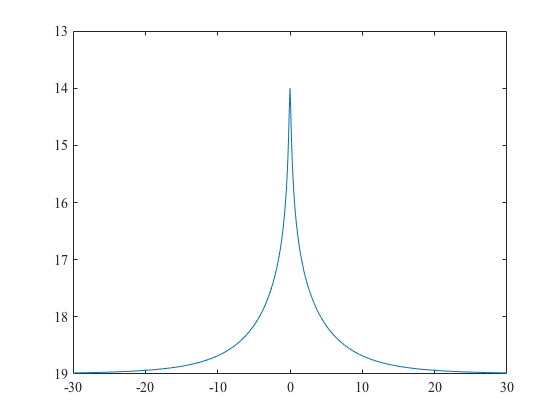

RAD = 180./pi;
[ER,T1,T2,Mu1,Mu2,TD1,TD2,Tcm]=AstroUtil.microlensing.pointsource_lens(1,5000,10000,5000,1./(1000.*RAD.*3600))

Alternatively, a more convinient function is `AstroUtil.microlensing.microlens_ps:`

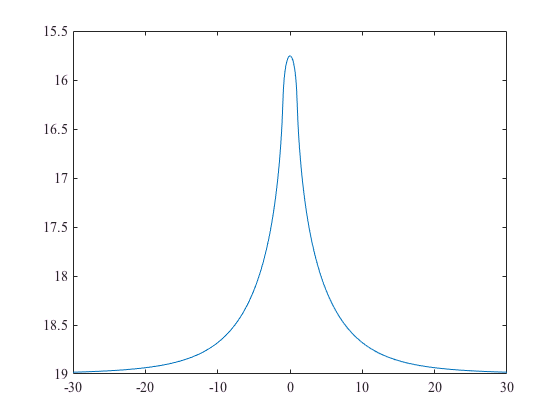

% microlensing parameters
Pars.T0   = 0;  % time of min. impact parameter
Pars.Beta = 0.01;  % impact parameters in units of the Einstein radsius
Pars.V    = 0.1;   % velocity [Einstein rdaius per day]

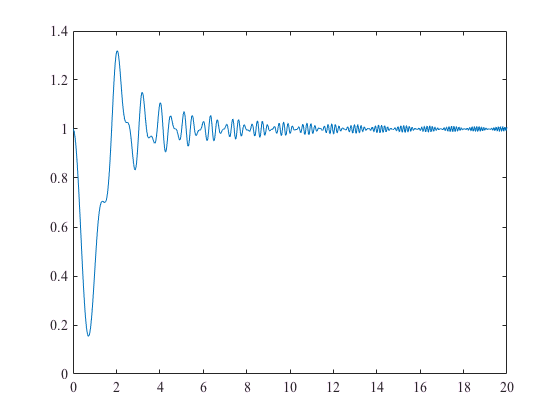

Pars.Alpha = 1;    % blensing parameter
Pars.BaseMag = 19; % Source base magnitude
Time = (-30:0.1:30).';
[Mag,Res]=AstroUtil.microlensing.microlens_ps(Pars,Time);
plot(Res.T,Mag); invy;
% or similarly with finate source effect
Pars.FS = 0.1;  % source size in units of the Einstein radius
[Mag,Res]=AstroUtil.microlensing.microlens_psfs(Pars,Time);

plot(Res.T,Mag); invy;

Similarly the function `AstroUtil.microlensing.microlens_psb` gets a list of source-lens distances (in units of the Einstein radius) instead of list of times, while the `AstroUtil.microlensing.microlens_pspar `function take into account the annual parallax.

## The Occultations package

The `Occultation` sub package provide some functions to calculate diffractive occultations:

The following example generate the intensity as a function of source-occulter distance (in Units of the Fresnel radii), for occulter which radius is 0.9 the Fresnel scale, assuming a point source and monochromatic light:

Dist = (0:0.01:20)';

C =      -0.16608


E =       0.25165


[I_rho,A_rho]=AstroUtil.Occultation.fresnel_occultation_ps(0.9,Dist);
plot(Dist,I_rho)

The function `AstroUtil.Occultation.fresnel_occultation_fs` take into account the finite source size, while the `AstroUtil.Occultation.fresnel_occultation_filt` function deal with finite source and polychromatic light.

## The stars package

The stars sub package contains astrophysical stars related functions.

The `AstroUtil.stars.star_ang_rad` function estimate the star angular radius from magnitude and colors.

The function AstroUtil.stars.star_sptype_color calculate the star color index given its spectral type and luminosity class. The following example calculate the SDSS AB *g-r* color index for and A3IV star:

[C,E]=AstroUtil.stars.star_sptype_color('A3','IV','SDSS','g','AB','SDSS','r','AB')

The following example calculate and plot the stellar evolutionary tracks (based on the Geneva stellar tracks):

[Ev,UBV]=AstroUtil.stars.stellar_tracks(1,0.04,'c');

## The supernova package

The `supernova` package is a collection of tools for supernovae research.

Several examples:

Calculate the nickel 56 -> Cobalt -> Iron energy production:

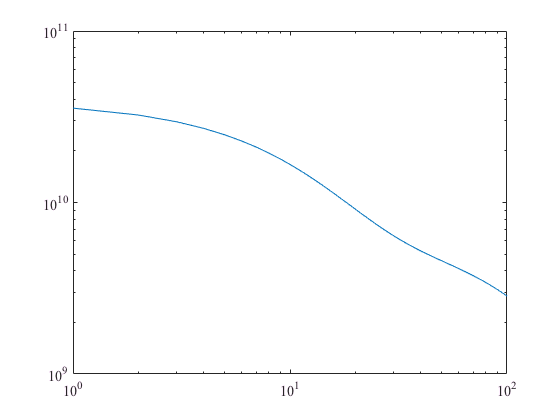

Time = (1:1:100)';

[E,E_Ni,E_Co]=AstroUtil.supernova.nickel56_decay(Time);
loglog(Time,E)

Additional functions contains the Rabinak & Waxman (2011) shock cooling model and more.